# Spiral pulley analysis

In this script the logarithic, constant force and achrimides spirals get optimized for their paramters by minimizing the resulting potential energy and keeping the resulting force positive.

These are then saved and used in the mass_transfer_spiral_type.mlx scripts for further analysis 

## General properties

clear all
r1 = 10; %m[mm]
r2 = 27.6; %[mm]
F0 = 37.278; %[N]
k = 1315e-3; %[N/mm] 
basic_spiral = spiral(r1,r2,F0,k); %initializing the spiral with given propertie

### Model properties

n_steps = 50; %resolution of a given spiral

max_offset = 20; %[mm] maximal spring offset
min_offset = -5; %[mm] minimal spring offset that will be optimized for
offset_stepsize = 1;
offsets = [min_offset:offset_stepsize:max_offset] %offsets which will be optimized for

offsets =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


# Optimizing logarithmic pulley

### Model  properties

theta_max = 1.5*pi; %[rad] maximal amount of rotation is one and a half
angle_stepsize = 0.1e-2; %stepsize of the optimization 
angles = [0.5:angle_stepsize:1]*pi/2; %angles that are going to be analyzed  

### optimization

clear best_spiral %clearing the best spiral object
lowest_avg = Inf; %setting the lowest average to infinity
avg_energy_sqr = zeros(1,length(angles));
for j = 1 : length(offsets)
    for i = 1: length(angles)
        logarithmic_spiral = basic_spiral.logarithmic(n_steps, theta_max, angles(i));
        logarithmic_spiral = logarithmic_spiral.complete_analysis(n_steps,offsets(j));
        avg_energy_sqr(i) = mean((logarithmic_spiral.Etot).^2); 
        %taking the square to have negative values not decrease the mean
        %and punnishing higher deviation from 0
        if avg_energy_sqr(i) <= lowest_avg
            if sum(logarithmic_spiral.Fres <= 0) == 0 %Fres < 0 is underisrable as the mass will drop
                %checking if the current average potential energy is lower than the
                %current best
                lowest_avg = avg_energy_sqr(i);
                best_spiral = logarithmic_spiral; %setting the new best potential energy 
            end
        end
    end
end

## Plotting the results

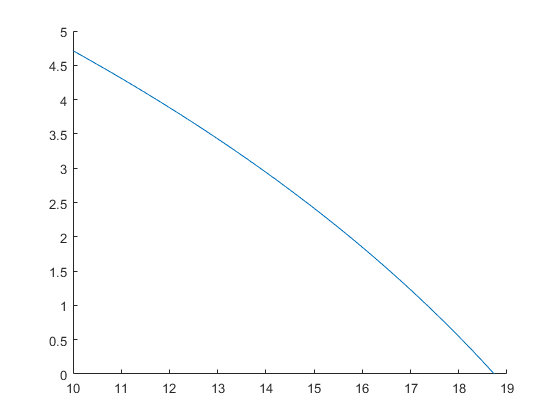

%plot(angles,avg_energy)
figure()
hold on
best_spiral = best_spiral.logarithmic(1000,theta_max,best_spiral.curve_angle); %drawing a higher resolution shape
%best_spiral = best_spiral.linear_extend(pi/6,100); %adding extension of the pulley

plot(best_spiral.r,best_spiral.theta)

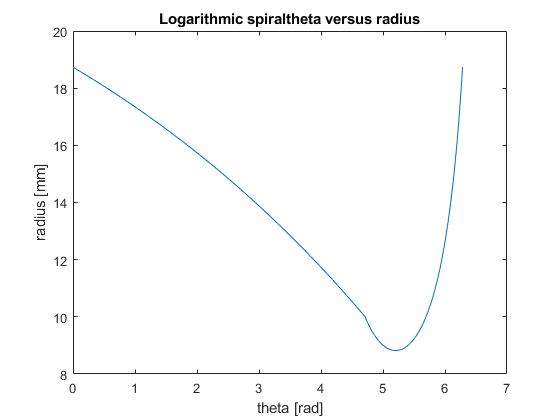

best_spiral = best_spiral.close_shape(300);
best_spiral.plot_r_theta()

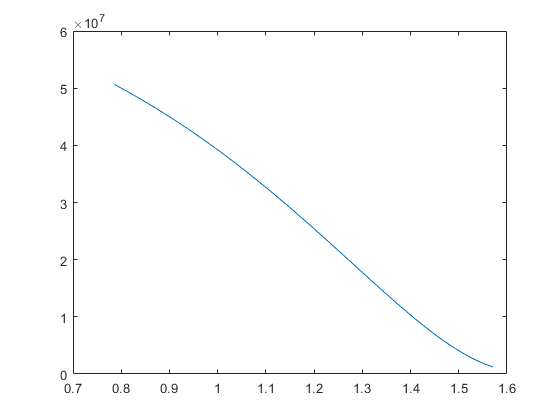

plot(angles,avg_energy_sqr)

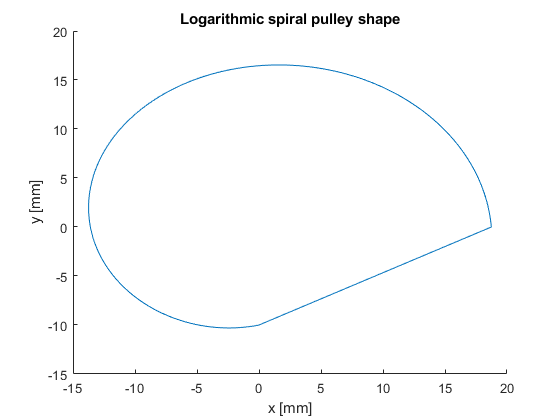

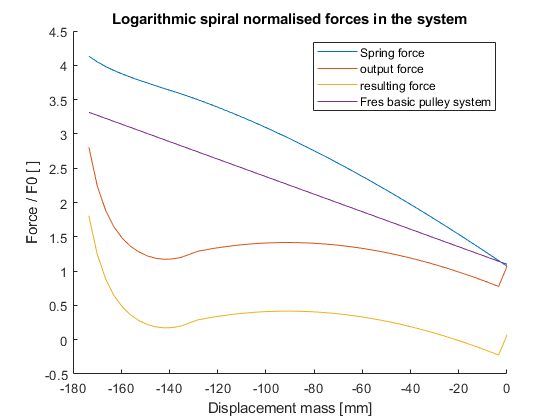

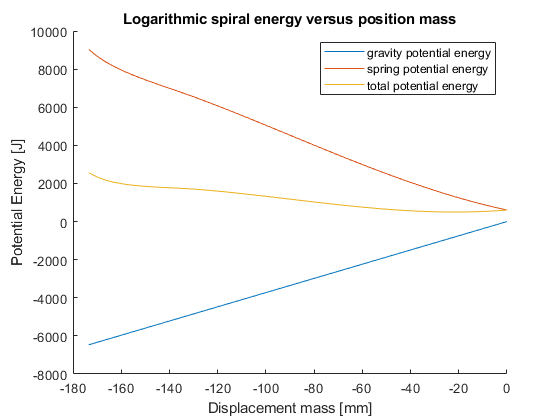

ans =   spiral with properties:

                   r1: 10
                   r2: 27.6000
                   F0: 37.2780
                    k: 1.3150
                 name: 'Logarithmic spiral'
                    S: []
                    r: [1×1301 double]
                theta: [1×1301 double]
                    x: [1×1301 double]
                    y: [1×1301 double]
    spiral_max_stroke: 173.4159
          curve_angle: 1.4263
                 x_m2: 173.4159
                  x_m: [1×51 double]
                  x_s: [1×51 double]
                   rs: [1×51 double]
                  phi: [1×51 double]
        spring_offset: 2
                   Fm: [1×51 double]
                   Fs: [1×51 double]
                 Fres: [1×51 double]
           Fm_control: [1×51 double]
                   Eg: [1×51 double]
                   Es: [1×51 double]
                 Etot: [1×51 double]


best_spiral.plot_all(n_steps,best_spiral.spring_offset-10)

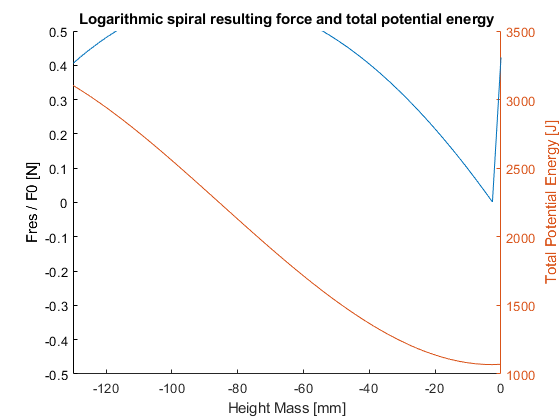

fig =   Figure (39) with properties:

      Number: 39
        Name: ''
       Color: [1 1 1]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


fig = best_spiral.plot_force_energy()

save('best_log_spiral.mat',"best_spiral")


# Optimizing Constant force pulley

%setting up the optimization for the outer radius
optimizationrange = 0.1*r2;
r2_min = r2 - 10

r2_min = 17.6000

r2_max = r2 + optimizationrange

r2_max = 30.3600

r_stepsize = (r2_max - r2_min)/50

r_stepsize = 0.2552

r2_optimize = [r2_min:r_stepsize:r2_max]

r2_optimize =    17.6000   17.8552   18.1104   18.3656   18.6208   18.8760   19.1312   19.3864   19.6416   19.8968   20.1520   20.4072   20.6624   20.9176   21.1728   21.4280   21.6832   21.9384   22.1936   22.4488   22.7040   22.9592   23.2144   23.4696   23.7248   23.9800   24.2352   24.4904   24.7456   25.0008   25.2560   25.5112   25.7664   26.0216   26.2768   26.5320   26.7872   27.0424   27.2976   27.5528   27.8080   28.0632   28.3184   28.5736   28.8288   29.0840   29.3392   29.5944   29.8496   30.1048



clear best_spiral %clearing the best spiral object
lowest_avg = Inf; %setting the lowest average to infinity
avg_energy_sqr = zeros(1,length(angles));


for i = 1: length(r2_optimize)
    cf_spiral = basic_spiral;
    cf_spiral.r2 =  r2_optimize(i); %setting the optimization radius 
    cf_spiral = cf_spiral.Spiral_constant_Force(n_steps); %creating spiral shape
    cf_spiral = cf_spiral.complete_analysis(n_steps,4); %performing the analysis
    avg_energy_sqr(i) = mean((cf_spiral.Etot).^2);  %computing the absolute average energy 
    %taking the square to take into account negative energy values and
    %punnishing higher deviation from 0
    if avg_energy_sqr(i) <= lowest_avg
        if max(cf_spiral.theta)*cf_spiral.r2 >= 100 %we want the system to reach a minimal stroke
            %checking if the current average potential energy is lower than the
            %current best
            lowest_avg = avg_energy_sqr(i);
            best_spiral = cf_spiral; %setting the new best potential energy 
        
        end
    end
end


## Plotting the results

max(best_spiral.theta)/(pi)*180; %if this is less then 180 we have to first extend the spiral and then close the shape
%ylim([-1 100000])
best_spiral = best_spiral.Spiral_constant_Force(1000);
best_spiral = best_spiral.linear_extend(pi/2,100); %
best_spiral = best_spiral.close_shape(200)

best_spiral =   spiral with properties:

                   r1: 10
                   r2: 30.3600
                   F0: 37.2780
                    k: 1.3150
                 name: 'Constant force spiral'
                    S: 860.6541
                    r: [1×1302 double]
                theta: [1×1302 double]
                    x: [1×1302 double]
                    y: [1×1302 double]
    spiral_max_stroke: 107.6855
          curve_angle: []
                 x_m2: 107.6855
                  x_m: [1×51 double]
                  x_s: [1×51 double]
                   rs: [1×51 double]
                  phi: [1×51 double]
        spring_offset: 4
                   Fm: [1×51 double]
                   Fs: [1×51 double]
                 Fres: [1×51 double]
           Fm_control: [1×51 double]
                   Eg: [1×51 double]
                   Es: [1×51 double]
                 Etot: [1×51 double]


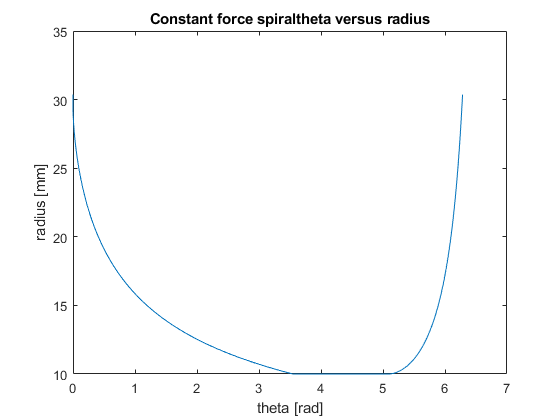

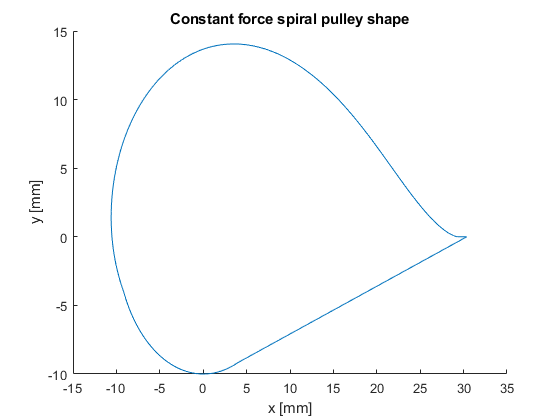

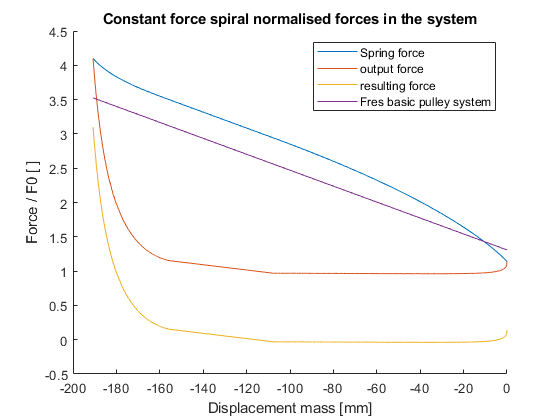

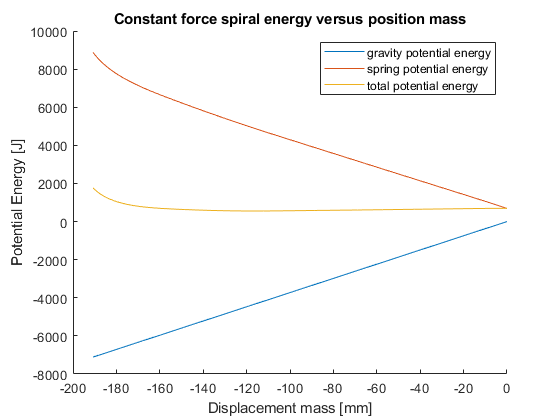

best_spiral =   spiral with properties:

                   r1: 10
                   r2: 30.3600
                   F0: 37.2780
                    k: 1.3150
                 name: 'Constant force spiral'
                    S: 860.6541
                    r: [1×1302 double]
                theta: [1×1302 double]
                    x: [1×1302 double]
                    y: [1×1302 double]
    spiral_max_stroke: 190.7575
          curve_angle: []
                 x_m2: 190.7575
                  x_m: [1×1001 double]
                  x_s: [1×1001 double]
                   rs: [1×1001 double]
                  phi: [1×1001 double]
        spring_offset: 4
                   Fm: [1×1001 double]
                   Fs: [1×1001 double]
                 Fres: [1×1001 double]
           Fm_control: [1×1001 double]
                   Eg: [1×1001 double]
                   Es: [1×1001 double]
                 Etot: [1×1001 double]

best_spiral = best_spiral.plot_all(1000,best_spiral.spring_offset)

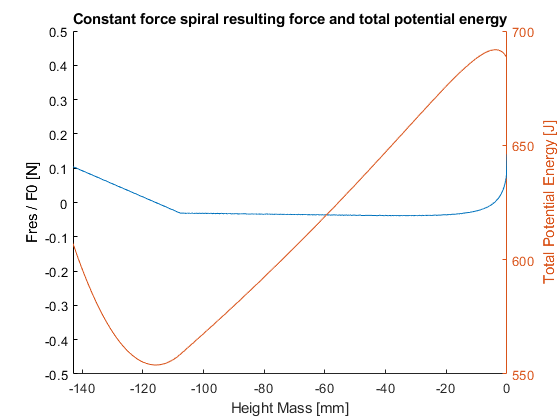

fig =   Figure (44) with properties:

      Number: 44
        Name: ''
       Color: [1 1 1]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


fig = best_spiral.plot_force_energy()

save('best_constant_spiral.mat',"best_spiral")


best_spiral.complete_analysis(1000,best_spiral.spring_offset -1);




# Optimizing Archimedes pulley

%setting up the optimization for the outer radius
optimizationrange = 2*r2;
r2_min = r2 - 5

r2_min = 22.6000

r2_max = r2 + optimizationrange;
r_stepsize = (r2_max - r2_min)/50

r_stepsize = 1.2040

r2_optimize = [r2_min:r_stepsize:r2_max]

r2_optimize =    22.6000   23.8040   25.0080   26.2120   27.4160   28.6200   29.8240   31.0280   32.2320   33.4360   34.6400   35.8440   37.0480   38.2520   39.4560   40.6600   41.8640   43.0680   44.2720   45.4760   46.6800   47.8840   49.0880   50.2920   51.4960   52.7000   53.9040   55.1080   56.3120   57.5160   58.7200   59.9240   61.1280   62.3320   63.5360   64.7400   65.9440   67.1480   68.3520   69.5560   70.7600   71.9640   73.1680   74.3720   75.5760   76.7800   77.9840   79.1880   80.3920   81.5960



clear best_spiral %clearing the best spiral object
lowest_avg = Inf; %setting the lowest average to infinity
avg_energy_sqr = zeros(1,length(angles));

for j = 1 : length(offsets)
    for i = 1: length(r2_optimize)
        archimedes_spiral = basic_spiral;
        archimedes_spiral.r2 =  r2_optimize(i); %setting the optimization radius 
        archimedes_spiral = archimedes_spiral.archimedes(n_steps,theta_max); %creating spiral shape
        archimedes_spiral = archimedes_spiral.complete_analysis(n_steps,offsets(j)); %performing the analysis
        avg_energy_sqr(i) = mean((archimedes_spiral.Etot).^2);  %computing the absolute average energy 
        %taking the square to take into account negative energy values and
        %punnishing higher deviation from 0
        if avg_energy_sqr(i) <= lowest_avg
                            lowest_avg = avg_energy_sqr(i);
                best_spiral = archimedes_spiral; %setting the new best potential energy 
            if sum(archimedes_spiral.Fres <= 0) == 100090 %Fres < 0 is underisrable as the mass will drop
                %checking if the current average potential energy is lower than the
                %current best

            end
        end
    end
end

## Plotting the results

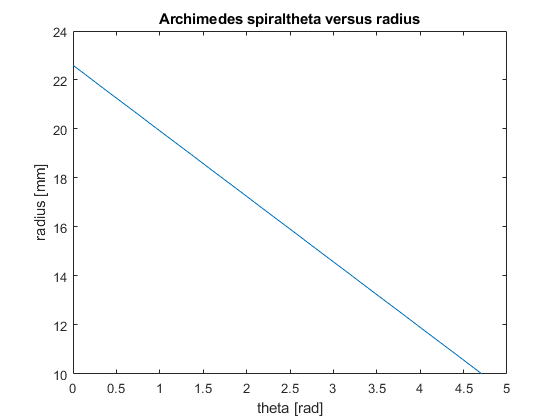

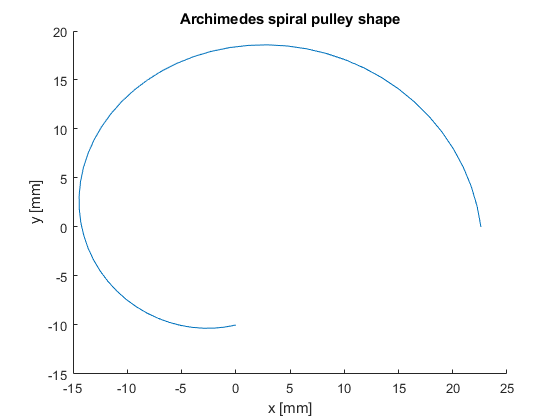

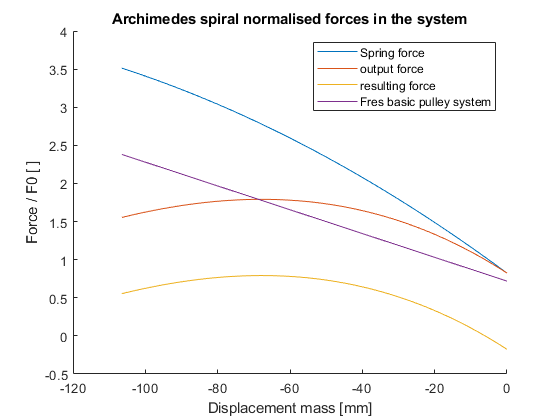

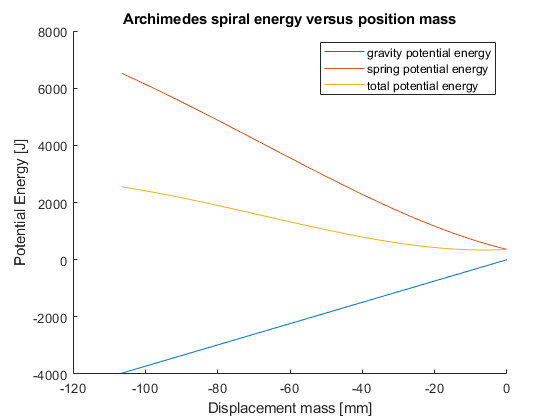

ans =   spiral with properties:

                   r1: 10
                   r2: 22.6000
                   F0: 37.2780
                    k: 1.3150
                 name: 'Archimedes spiral'
                    S: []
                    r: [1×51 double]
                theta: [1×51 double]
                    x: [1×51 double]
                    y: [1×51 double]
    spiral_max_stroke: 106.5000
          curve_angle: []
                 x_m2: 106.5000
                  x_m: [1×51 double]
                  x_s: [1×51 double]
                   rs: [1×51 double]
                  phi: [1×51 double]
        spring_offset: -5
                   Fm: [1×51 double]
                   Fs: [1×51 double]
                 Fres: [1×51 double]
           Fm_control: [1×51 double]
                   Eg: [1×51 double]
                   Es: [1×51 double]
                 Etot: [1×51 double]



%ylim([-1 100000])
best_spiral.plot_all(n_steps,best_spiral.spring_offset)